**EE-414 Speech Processing Lab**

**Lab-5 : PHASE -1**

**14/02/2021**

**AIM**

- To study different sound units present in majority of Indian languages.

- To understand the production mechanism of each sound unit.

- To learn the time domain and frequency domain characteristics of different sound units.

**THEORY**

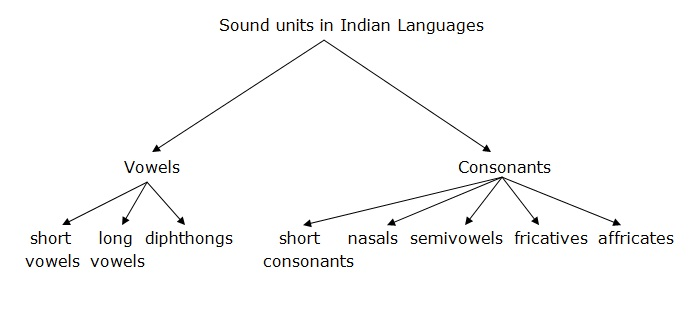

Classification Of Sound Units In Indian Languages:

The sound units are classified into two broad categories are mainly based on the **shape of the vocal tract.**

**A ) **Vowels : vocal tract shape is wide open without any constriction along its length starting from the glottis till the lips and is excited by voiced excitation source.

B ) Consonants : There may be constriction in vocal tract shape some where along its length and is excited by either voiced, unvoiced and both types of excitation.

**PROBLEM STATEMENT : A - Short Vowels, Long Vowels, and Diphthongs**

**Theory : **Vowels can be further divided into 3 types: Short vowels, long vowels, diphthongs

1) From the production process point of view there is no distinction between short and long vowels, except that the **duration of production will be longer, typically nearly double that of short vowels.**

**2) **In case of diphthongs, as the name indicates, two vowel sounds are produced in succession without any pause. The production process is such that the vocal tract shape is initially producing the first vowel and midway during the production of the first vowel it changes the shape to produce the other vowel .

**Procedure : **

a) Record the sounds of any one short vowel sound, long vowel sound and a diphthong (Also, record the two sounds present in the diphthong).

Short vowel : |a|  

Long vowel : |aa|

Diphthong : |ai| (a + e)

[y1,Fs] = audioread('short_vowel.wav');
sound(y1,Fs);
[y2,Fs] = audioread('long_vowel.wav');
sound(y2,Fs);
[y3,Fs] = audioread('dipthong.wav');
sound(y3,Fs);

b) Plot the time domain waveform, magnitude spectrum and the spectrogram for each of the above sounds.

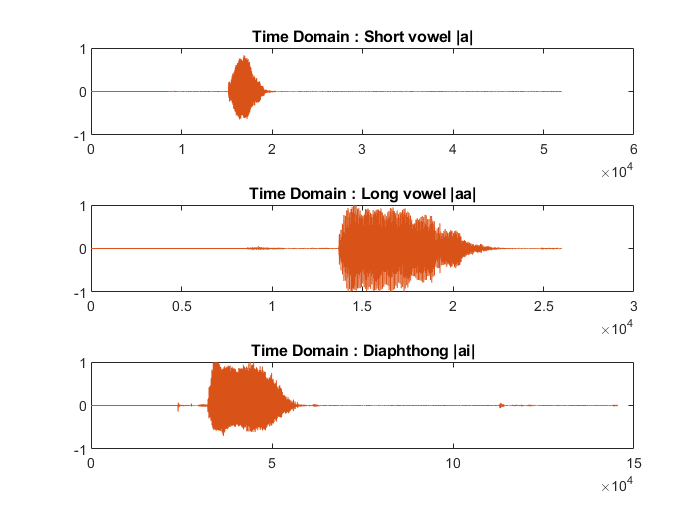

figure();
subplot(3,1,1);
plot(y1);
title('Time Domain : Short vowel |a|');
subplot(3,1,2);
plot(y2);
title('Time Domain : Long vowel |aa|');
subplot(3,1,3);
plot(y3);
title('Time Domain : Diaphthong |ai|');      

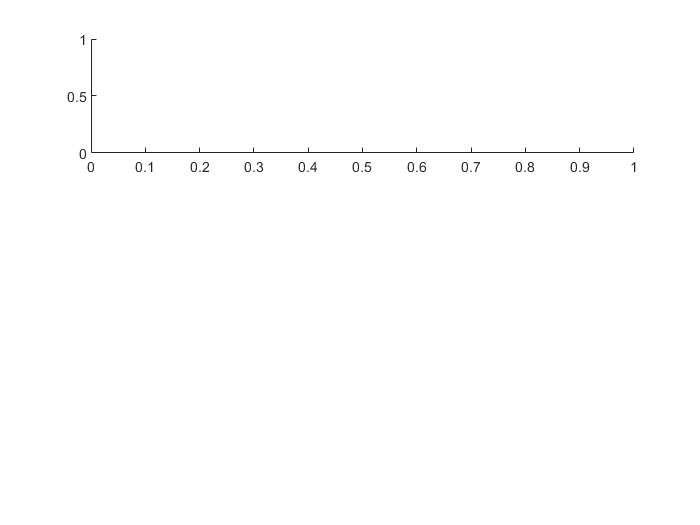

fs = 16000;
t = 0:1/fs:1-1/fs;
%Next, calculate the frequency axis, which is defined by the sampling rate
f = fs/2*linspace(-1,1,fs);

%Take fourier transform and apply fftshift
fftSignal = fft(y1);
fftSignal1 = fftshift(fftSignal);
fftSignal = fft(y2);
fftSignal2 = fftshift(fftSignal);
fftSignal = fft(y3);
fftSignal3 = fftshift(fftSignal);

%Since the signal is complex, we need to plot the magnitude to get it to
%look right, so we use abs (absolute value)
figure;
subplot(3,1,1)

plot(f, abs(fftSignal1));

Error using plot
Vectors must be the same length.

title('magnitude spectrum of Short Vowel');
xlabel('Frequency (Hz)');
ylabel('magnitude');
subplot(3,1,2)
plot(f, abs(fftSignal2));
title('magnitude spectrum of Long Vowel');
xlabel('Frequency (Hz)');
ylabel('magnitude');
subplot(3,1,3)
plot(f, abs(fftSignal3));
title('magnitude spectrum of Diapthong');
xlabel('Frequency (Hz)');
ylabel('magnitude');